# Load Laser Scan Data from File

Load a down-sampleed data set consisting of laser scans collected from a mobile robot in an indoor environment. The average displacement between every two scans is around 0.6 meters

% uncomment the below line for using the warehouse dataset
 data = load('offlineSlamData.mat'); 
 lines = data(1);
 disp(lines)

    scans: {1×71 cell}



whos("lines")

  Name       Size             Bytes  Class     Attributes

  lines      1x1             315479  struct              



fieldnames(lines(1))

ans = 1×1 cell array
    {'scans'}


# Run SLAM Algorithm, Construct Optimized Map and Plot Trajectory of the Robot

maxLidarRange = 8;
mapResolution = 20;
slamAlg = lidarSLAM(mapResolution, maxLidarRange);
slamAlg.LoopClosureThreshold = 210;  
slamAlg.LoopClosureSearchRadius = 8;

# Observe the Map building Process with initial 10 scans

for i=1:10
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if isScanAccepted
        fprintf('Added scan %d \n', i);
    end
end

figure;
show(slamAlg);
title({'Map of the Environment','Pose Graph for Initial 10 Scans'});

# Observe the effect of loop closures and the optimization process

for i=10:length(scans)
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if ~isScanAccepted
        continue;
    end
end 

# Visualize the Contructed Map and Trajectory of the Robot

figure
show(slamAlg);
title({'Final Built Map of the environment', 'Trajectory of the Robot'});

# Build Occupancy Grid Map

[scans, optimizedPoses]  = scansAndPoses(slamAlg);
map = buildMap(scans, optimizedPoses, mapResolution, maxLidarRange);
figure; 
show(map);
hold on
show(slamAlg.PoseGraph, 'IDs', 'off');
hold off
title('Occupancy Grid Map Built Using Lidar SLAM');


# -------------------------------------------------------------------------------------------------------------------------------

# Working on CSAIL-Newcarmen data

### CSAIL dataset

% Following is the dataset from CSAIL lab by Cyrill Stachniss
filepath = '../csail-newcarmen.log.gz'
gunzip(filepath);

% load the log file in MATLAB
fid = fopen('../csail-newcarmen.log', 'r'); % Open the file for reading
data = textscan(fid, '%s', 'Delimiter', '\n'); % Read all lines
disp(data{1}(1:30))

    {'# CARMEN Logfile'                                                                                                                                                                                                                                                                     }
    {'# file format is one message per line'                                                                                                                                                                                                                                                }
    {'# message_name [message contents] ipc_timestamp ipc_hostname logger_timestamp'                                                                                                                                                                                                        }
    {'# message formats defined: PARAM SYNC ODOM RAWLASER1 RAWLASER2 RAWLASER3 RAWLASER4 ROBOTLASER0 ROBOTLASER1 FLASER RLASER LASER3 LASER4' 


fclose(fid);

lines = data{1}; % Extract text lines

% extract laser scan data
laserScans = {}; % Initialize storage for scans
for i = 1:length(lines)
    if contains(lines{i}, 'ROBOTLASER1') % Check if the line contains a laser scan
        laserScans{end+1} = strsplit(lines{i}); % Split by spaces
    end
end

checking how many value seach FLASER line contains

for i = 1:min(10, length(laserScans))
    disp(laserScans{i});
end

    {'#'}    {'message'}    {'formats'}    {'defined:'}    {'PARAM'}    {'SYNC'}    {'ODOM'}    {'RAWLASER1'}    {'RAWLASER2'}    {'RAWLASER3'}    {'RAWLASER4'}    {'ROBOTLASER0'}    {'ROBOTLASER1'}    {'FLASER'}    {'RLASER'}    {'LASER3'}    {'LASER4'}

    {'#'}    {'ROBOTLASER1'}    {'laser_type'}    {'start_angle'}    {'field_of_view'}    {'angular_resolution'}    {'maximum_range'}    {'accuracy'}    {'remission_mode'}    {'num_readings'}    {'[range_readings]'}    {'laser_pose_x'}    {'laser_pose_y'}    {'laser_pose_theta'}    {'robot_pose_x'}    {'robot_pose_y'}    {'robot_pose_theta'}    {'laser_tv'}    {'laser_rv'}    {'forward_safety_dist'}    {'side_safty_dist'}

    {'ROBOTLASER1'}    {'0'}    {'-1.570796'}    {'3.141593'}    {'0.008727'}    {'81.920000'}    {'0.050000'}    {'0'}    {'361'}    {'1.40'}    {'1.39'}    {'1.39'}    {'1.39'}    {'1.38'}    {'1.36'}    {'1.37'}    {'1.36'}    {'1.35'}    {'1.34'}    {'1.34'}    {'1.33'}    {'1.33'}    {'1.32'}    {'1.32'}    {'1

% convert the data to MATLAB format
numScans = length(laserScans);

scanData = [];
for i = 1:numScans
    values = str2double(laserScans{i}(2:end)); % Convert string to double
    if length(values) >= 180 % Ensure we have enough values
        scanData(i, :) = values(1:180); % Append valid scans
    else
        warning("Skipping scan %d: Not enough readings (%d found)", i, length(values));
        continue;
    end
end

save('../csail-newcarmen.mat', 'scanData');


% load the data
load('../csail-newcarmen.mat')
data = load('../csail-newcarmen.mat');
laserScans_data = data.scanData;

numScans = size(laserScans_data, 2)

numScans = 180


% Parameters for SLAM
maxLidarRange = 8;   % Adjust based on your sensor
mapResolution = 20;   % Map resolution in cells per meter

% Initialize the lidarSLAM object
slamObj = lidarSLAM(mapResolution, maxLidarRange);
slamObj.LoopClosureThreshold = 80;  % Set loop closure sensitivity
slamObj.LoopClosureSearchRadius = 5; % Search radius for loop closure

% initialize SLAM parameters
numScans = size(laserScans_data, 1); % Number of scans
numRanges = size(laserScans_data, 2); % Number of measurements per scan
angles = linspace(-pi, pi, numRanges); % Generate angle values for scan

% Process each laser scan and add it to the SLAM algorithm
scans = {};
for i = 1:5:numScans
    % Ensure all values are nonnegative
    validRanges = max(laserScans_data(i, :), 0); % Clip negative values to zero
     % Check if scan is valid (avoid mostly empty scans)
    if sum(validRanges) > 10 % Ensure at least some valid readings
        scan = lidarScan(validRanges, angles); % Create lidarScan object
        scans{end+1} = scan; % Store scan
        addScan(slamObj, scan); % Add scan to SLAM
    else
        warning("Skipping scan %d: Mostly empty readings.", i);
    end
end

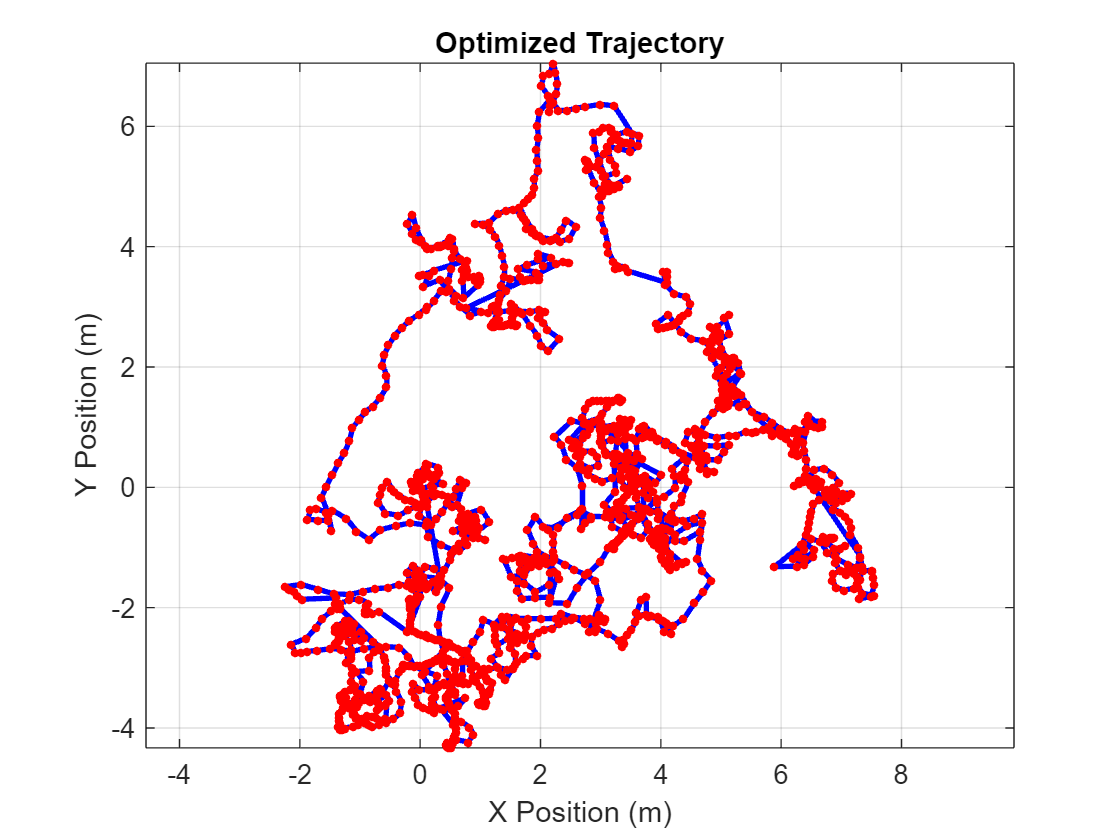

% Build the optimized map
[scansOptimized, optimizedPoses] = scansAndPoses(slamObj);

% Plot the optimized trajectory
figure;
plot(optimizedPoses(:,1), optimizedPoses(:,2), 'b-', 'LineWidth', 2);
hold on;
scatter(optimizedPoses(:,1), optimizedPoses(:,2), 10, 'r', 'filled');
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Optimized Trajectory');
axis equal;
grid on;